# Lista dodatkowa — zastosowania MATLAB-a w fizyce

## Zad. 1. Obwód elektryczny

Trzy oporniki $R_1 = 100\,\Omega$, $R_2 = 220\,\Omega$ i $R_3 = 330\,\Omega$ połączono równolegle. Do układu przyłożono napięcie $U = 12\,\mathrm{V}$. Natężenie prądu i moc: $I = \frac{U}{R}$, $P = \frac{U^2}{R}$.

a) Zapisz opory w jednym wektorze wierszowym. Oblicz wektory natężeń prądów i mocy, wykonując działania na całych wektorach.

b) Utwórz macierz o kolumnach: opór [Ω], natężenie prądu [A], moc [W]. Każdy wiersz powinien odpowiadać jednemu opornikowi.

c) Korzystając z indeksowania, wybierz dane drugiego opornika oraz kolumnę zawierającą moce.

d) Oblicz opór zastępczy $R_z = \frac{1}{\frac{1}{R_1}+\frac{1}{R_2}+\frac{1}{R_3}}$. Sprawdź, czy suma prądów jest równa $\frac{U}{R_z}$, a suma mocy $\frac{U^2}{R_z}$. Wykorzystaj `sum`.

%a -------------
R = [100 220 330];
U = 12;

I = U./R

I =     0.1200    0.0545    0.0364


P = U.^2./R

P =     1.4400    0.6545    0.4364



%b -------------
data1 = [R;I;P]'

data1 =   100.0000    0.1200    1.4400
  220.0000    0.0545    0.6545
  330.0000    0.0364    0.4364



%c -------------
data2 = data1(2,:)

data2 =   220.0000    0.0545    0.6545


data3 = data1(:,3)

data3 =     1.4400
    0.6545
    0.4364



%d -------------
R_z = 1/( ...
    1/R(1)+ ...
    1/R(2)+ ...
    1/R(3))

R_z = 56.8966


a = sum(I); b = U/R_z;
disp([a b sum(I) == U/R_z]);

    0.2109    0.2109    1.0000




format long
a = sum(P); b = U^2/R_z;
disp([a b sum(P) == U^2/R_z]);

   2.530909090909091   2.530909090909091                   0




format short

## Zad. 2. Siła wypadkowa i przyspieszenie

Na ciało o masie $m = 2\,\mathrm{kg}$ działają siły: $F_1 = 6\,\mathrm{N}$ pod kątem $30^\circ$, $F_2 = 4\,\mathrm{N}$ pod kątem $150^\circ$, $F_3 = 3\,\mathrm{N}$ pod kątem $270^\circ$.

Kąty mierzone są przeciwnie do ruchu wskazówek zegara od dodatniego kierunku osi x. Składowe: $F_x = F\cos(\alpha)$, $F_y = F\sin(\alpha)$.

a) Oblicz składowe sił, korzystając z `sind` i `cosd`. Zapisz każdą siłę jako wektor dwuelementowy.

b) Oblicz wektor siły wypadkowej $\vec{F}_w = \vec{F}_1 + \vec{F}_2 + \vec{F}_3$ oraz jego długość $|\vec{F}_w| = \sqrt{F_{wx}^{2}+F_{wy}^{2}}$.

c) Oblicz wektor przyspieszenia $\vec{a} = \frac{\vec{F}_w}{m}$ i jego długość.

d) Przygotuj dwa podwykresy za pomocą `subplot`. Na pierwszym przedstaw trzy siły i ich wypadkową zaczepione w początku układu. Na drugim przedstaw przyspieszenie i jego składowe. Użyj `quiver` ze skalowaniem 0 oraz `axis equal`.

%a ------------
F_1 = [6*cosd(30),6*sind(30)]

F_1 =     5.1962    3.0000


F_2 = [4*cosd(150),4*sind(150)]

F_2 =    -3.4641    2.0000


F_3 = [3*cosd(270),3*sind(270)]

F_3 =      0    -3



%b ------------
F_w = F_1 + F_2 + F_3

F_w =     1.7321    2.0000


F_w_len = sqrt(F_w(1)^2+F_w(2)^2)

F_w_len = 2.6458


%c ------------
m = 2

m = 2

a = F_w./m

a =     0.8660    1.0000


a_len = sqrt(a(1)^2+a(2)^2)

a_len = 1.3229

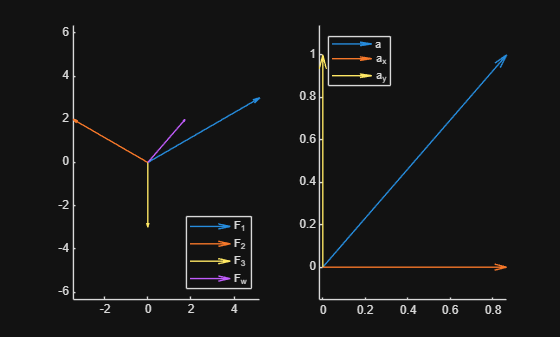


%d ------------
clf;

subplot(1,2,1)
hold on

quiver(0,0,  F_1(1), F_1(2), 0)
quiver(0,0,  F_2(1), F_2(2), 0)
quiver(0,0,  F_3(1), F_3(2), 0)
quiver(0,0,  F_w(1), F_w(2), 0)
legend("F_1","F_2","F_3","F_w","Location","southeast")
axis equal

hold off

subplot(1,2,2)
hold on
quiver(0,0, a(1),a(2), 0)
quiver(0,0, a(1),0, 0)
quiver(0,0, 0,a(2), 0)
legend("a","a_x","a_y","Location","northwest")

axis equal
hold off

## Zad. 3. Rzut ukośny

Piłkę wyrzucono z poziomu ziemi z prędkością $v_0 = 15\,\mathrm{m/s}$. Pomijamy opór powietrza. Przyjmij $g = 9{,}81\,\mathrm{m/s^2}$.

Równania ruchu: $x(t) = v_0\cos(\alpha)\,t$, $y(t) = v_0\sin(\alpha)\,t - \frac{gt^2}{2}$. Czas lotu: $t_k = \frac{2v_0\sin(\alpha)}{g}$.

a) Dla $\alpha = 30^\circ$ oblicz czas lotu. Za pomocą funkcji `linspace` utwórz wektor zawierający 200 równomiernie rozmieszczonych wartości czasu od 0 do $t_k$, a następnie oblicz współrzędne x i y.

b) Powtórz obliczenia dla $45^\circ$ i $60^\circ$. Dla każdego kąta utwórz osobny wektor czasu obejmujący cały lot.

c) Narysuj trzy tory na jednym wykresie, korzystając z `plot(x,y)` i `hold on`.

d) Odczytaj zasięgi jako ostatnie elementy wektorów x. Który z badanych kątów daje największy zasięg? Porównaj wyniki dla $30^\circ$ i $60^\circ$.

v_0 = 15

v_0 = 15

g = 9.81

g = 9.8100


x = @(t,a) v_0*cosd(a).*t;
y = @(t,a) v_0*sind(a).*t - (g*t.^2)/2;
t = @(a) (2*v_0)*sind(a)/g;

%a ------------

t_k = t(30)

t_k = 1.5291

w = linspace(0,t_k,200)

w =          0    0.0077    0.0154    0.0231    0.0307    0.0384    0.0461    0.0538    0.0615    0.0692    0.0768    0.0845    0.0922    0.0999    0.1076    0.1153    0.1229    0.1306    0.1383    0.1460    0.1537    0.1614    0.1690    0.1767    0.1844    0.1921    0.1998    0.2075    0.2151    0.2228    0.2305    0.2382    0.2459    0.2536    0.2612    0.2689    0.2766    0.2843    0.2920    0.2997    0.3073    0.3150    0.3227    0.3304    0.3381    0.3458    0.3534    0.3611    0.3688    0.3765



x_1 = x(w,30)

x_1 =          0    0.0998    0.1996    0.2994    0.3993    0.4991    0.5989    0.6987    0.7985    0.8983    0.9981    1.0980    1.1978    1.2976    1.3974    1.4972    1.5970    1.6968    1.7967    1.8965    1.9963    2.0961    2.1959    2.2957    2.3955    2.4953    2.5952    2.6950    2.7948    2.8946    2.9944    3.0942    3.1940    3.2939    3.3937    3.4935    3.5933    3.6931    3.7929    3.8927    3.9926    4.0924    4.1922    4.2920    4.3918    4.4916    4.5914    4.6913    4.7911    4.8909


y_1 = y(w,30)

y_1 =          0    0.0573    0.1141    0.1703    0.2259    0.2809    0.3353    0.3892    0.4425    0.4952    0.5473    0.5989    0.6498    0.7002    0.7500    0.7993    0.8479    0.8960    0.9435    0.9904    1.0367    1.0825    1.1276    1.1722    1.2163    1.2597    1.3026    1.3448    1.3865    1.4277    1.4682    1.5082    1.5475    1.5864    1.6246    1.6622    1.6993    1.7358    1.7717    1.8070    1.8418    1.8759    1.9095    1.9425    1.9750    2.0068    2.0381    2.0688    2.0989    2.1285



%b ------------
t_k = t(45);
w = linspace(0,t_k,200)

w =          0    0.0109    0.0217    0.0326    0.0435    0.0543    0.0652    0.0761    0.0869    0.0978    0.1087    0.1195    0.1304    0.1413    0.1521    0.1630    0.1739    0.1847    0.1956    0.2065    0.2173    0.2282    0.2391    0.2499    0.2608    0.2717    0.2825    0.2934    0.3043    0.3151    0.3260    0.3369    0.3477    0.3586    0.3695    0.3803    0.3912    0.4021    0.4129    0.4238    0.4347    0.4455    0.4564    0.4673    0.4781    0.4890    0.4999    0.5107    0.5216    0.5325



x_2 = x(w,45);
y_2 = y(w,45);

% ---
t_k = t(60);
w = linspace(0,t_k,200)

w =          0    0.0133    0.0266    0.0399    0.0532    0.0665    0.0799    0.0932    0.1065    0.1198    0.1331    0.1464    0.1597    0.1730    0.1863    0.1996    0.2129    0.2262    0.2396    0.2529    0.2662    0.2795    0.2928    0.3061    0.3194    0.3327    0.3460    0.3593    0.3726    0.3859    0.3993    0.4126    0.4259    0.4392    0.4525    0.4658    0.4791    0.4924    0.5057    0.5190    0.5323    0.5456    0.5590    0.5723    0.5856    0.5989    0.6122    0.6255    0.6388    0.6521


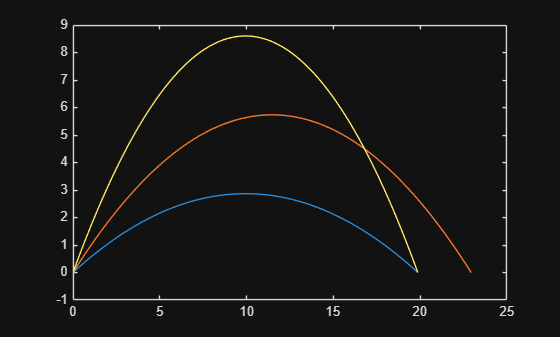


x_3 = x(w,60);
y_3 = y(w,60);

%c ------------
clf;
plot(x_1,y_1)
hold on
plot(x_2,y_2)
plot(x_3,y_3)


%d ------------
disp(["x_1" x_1(end); ...
    "x_3" x_3(end); ...
    "Czy jest taki sam?" round(x_1(end)==x_3(end)) ...
    ]);

    "x_1"                   "19.863"
    "x_3"                   "19.863"
    "Czy jest taki sam?"    "1"     



hold off

## Zad. 4. Odbijająca się piłka

Piłkę puszczono z wysokości $h_0 = 2\,\mathrm{m}$. Po każdym odbiciu osiąga wysokość równą $r = 0{,}7$ poprzedniej wysokości. Wysokość po n-tym odbiciu: $h_n = h_0 r^n$.

a) Utwórz wektor numerów odbić od 0 do 10 i oblicz wysokości. Wartość dla $n = 0$ oznacza wysokość początkową.

b) Narysuj wysokość w zależności od numeru odbicia. Zaznacz wyniki kółkami bez łączenia ich linią.

c) Oblicz drogę od puszczenia piłki do ponownego dotknięcia podłoża po dziesiątym odbiciu: $D_{10} = h_0 + 2(h_1 + h_2 + \cdots + h_{10})$. Użyj indeksowania i `sum`. Wyjaśnij czynnik 2.

d) Porównaj wynik z drogą dla nieskończenie wielu odbić: $D_\infty = h_0 + \frac{2h_0r}{1-r}$. Oblicz $D_\infty - D_{10}$. Powtórz obliczenie dla 50 odbić i skomentuj zmianę różnicy.

r = 0.7

r = 0.7000

h_0 = 2

h_0 = 2

h_n = @(n) h_0*r.^n;

%a ------------
h = h_n(0:10)

h =     2.0000    1.4000    0.9800    0.6860    0.4802    0.3361    0.2353    0.1647    0.1153    0.0807    0.0565


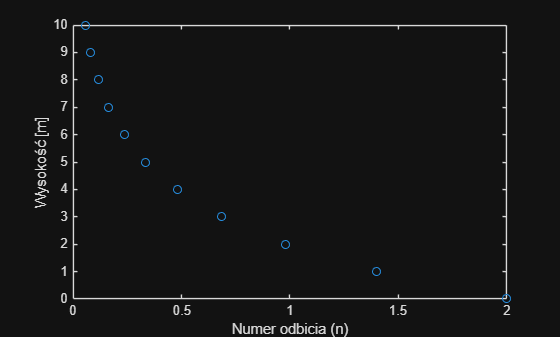


%b ------------
clf
plot(h,0:10,"o")
xlabel("Numer odbicia (n)")
ylabel("Wysokość [m]")


%c ------------
D_10 = sum(h_0 + 2*(h(1:10)))

D_10 = 32.9567

%czynnik 2 uwzględnia drogę powrotną piłki



## Zad. 5. Ruch po linii śrubowej

Cząstka wykonuje ruch po okręgu w płaszczyźnie xy, jednocześnie przemieszczając się ze stałą prędkością wzdłuż osi z.

Równania: $x(t) = R\cos(\omega t)$, $y(t) = R\sin(\omega t)$, $z(t) = v_z t$. Przyjmij $R = 0{,}5\,\mathrm{m}$, $\omega = \pi\,\mathrm{rad/s}$ oraz $v_z = 0{,}2\,\mathrm{m/s}$.

a) Utwórz wektor czasu od 0 do 6 s z krokiem 0,01 s. Oblicz współrzędne cząstki. Użyj `sin` i `cos` (argument w radianach).

b) Narysuj tor za pomocą `plot3`. Opisz trzy osie. Zastosuj `grid on` i `axis equal`.

c) W osobnym oknie przygotuj dwa podwykresy: rzut toru na płaszczyznę xy - `plot(x,y)`, oraz na płaszczyznę xz - `plot(x,z)`.

d) Oblicz okres obiegu $T = \frac{2\pi}{\omega}$ oraz skok linii śrubowej $p = v_z T$. Zwiększ $v_z$ dwukrotnie i narysuj nowy tor razem z poprzednim. Opisz zmianę kształtu toru.